addpath C:\Users\nlab\Desktop\GitHub\ratrix\analysis\KC
addpath C:\Users\nlab\Desktop\GitHub\ratrix\analysis\KC\in_progress_code
addpath C:\Users\nlab\Desktop\GitHub\ratrix\analysis\KC\code_shared_groupNind
addpath C:\Users\nlab\Desktop\GitHub\ratrix\analysis\KC\group_analyses_code
addpath C:\Users\nlab\Desktop\GitHub\ratrix\analysis\KC\individual_analysis_code

% make vector of stim conditions in order of presentation/trial,
% & list of unique stim params (for looping)
[conOrderedByTrialMeetCriteria,uniqueContrasts,durOrderedByTrialMeetCriteria,uniqueDurations,conAndDurOrderedByTrialMeetCriteria] = getStimParamsNtrialConds(stimDetails,trialCond,idxOnsetsMeetsCriteria);

% in preparation for making pixel wise figures of flurescene at different stim conditions,
% make figure legends
[reigons,cons4Legend,cons4axes,durs4Legend,durs4Axes] = getSubtitleLegendNaxesInfo(uniqueContrasts,uniqueDurations);
reigons

reigons =     'V1'    'LP-HVA'    'LA-HVA'    'MA-HVA'    'control'


cons4Legend

cons4Legend =     '0'    '0.03'    '0.0625'    '0.125'    '0.25'    '0.5'    '1'


durs4Legend

durs4Legend =     '1'    '2'    '4'    '8'    '16'


% make duration legend
dursInSec = uniqueDurations/10;
for d = 1:length(dursInSec)

    dursInSecAsStrings = arrayfun(@num2str, dursInSec, 'UniformOutput', 0);

    legendStrings{d} = sprintf('%s %s', dursInSecAsStrings{d},'sec');

end 

    legendStrings

legendStrings =     '0.1 sec'    '0.2 sec'    '0.4 sec'    '0.8 sec'    '1.6 sec'


% SHOW IMAGES for each STIM COND (con dur combo) at PEAK response

% SELECT RANGE for IMAGESC to SHOW PIX WISE IMAGES
range = input('FIG 1: from 0-1, what range values to use? Enter in bracket form with low & high end values: ') % don't need to save range var out cuz don't need it in following functions/code, just display it 

range =          0    0.0500


colorMapOrNot = input('use colormap jet or no (yes = 1, no = 2)?: ')

colorMapOrNot = 1


clear spNum
spNum = 1; % using subplotNum to index subplots since neither uniqueCon or uniqueDur have the right values

fig = figure; % one fig all images % need fig var to alter axes later

clear titleText
titleText = ': PEAK cortical response to each UNIQUE stim condition'; % making char variables for sprintf/title later
%suptitle(sprintf('%s', date, subjName, titleText));

% index into trials for each combo of DUR & CON @ peak frames

% for each contrast (row):
for c = 1:length(uniqueContrasts)

    % going to show pix wise image for cth contrast (row) at each duration (column)
    for d = 1:length(uniqueDurations)

        % select for trials at the cth contrast & dth duration
        clear cthDthTrials 
        cthDthTrials = conAndDurOrderedByTrialMeetCriteria(1,:) == uniqueContrasts(c) & conAndDurOrderedByTrialMeetCriteria(2,:) == uniqueDurations(d);
        %numCthDthTrials = sum(cthDthTrials)

         clear cthDthPeakImage
         % get MEAN PEAK activity IMAGE across CTHDTH TRIALS
         allPeakFramesCthDthtrialsOnsetDf = onsetDf(:,:,peakFrameIdx,cthDthTrials); % index into peak frames & cth dth trials
         mnPeakFramesCthDthtrialsOnsetDf = mean(allPeakFramesCthDthtrialsOnsetDf,3); % mean over peak frames
         mnPeakFramesCthDthtrialsOnsetDf = squeeze(mnPeakFramesCthDthtrialsOnsetDf); % squeeze
         mnPeakFramesMnCthDthtrialsOnsetDf = mean(mnPeakFramesCthDthtrialsOnsetDf,3); % mean over cthdth trials
         meanPeakImageCthDthTrials = squeeze(mnPeakFramesMnCthDthtrialsOnsetDf); % squeeze

         % get BASEline IMAGE at cthdth trials
         allBaseFramesCthDthtrials = onsetDf(:,:,baselineIdx,cthDthTrials); % index
         meanBaseFramesCthDthtrials = mean(allBaseFramesCthDthtrials,3); % mean over baseline frames
         meanBaseFramesCthDthtrials = squeeze(meanBaseFramesCthDthtrials); % squeeze
         meanBaseFramesCthDthtrials = mean(meanBaseFramesCthDthtrials,3); % mean over trials
         meanBaseImageCthDthtrials = squeeze(meanBaseFramesCthDthtrials); % squeeze

         % SUBTRACT BASELINE from MEAN PEAK ACTIVITY IMAGE for CTHDTH TRIALS
         % just subtracting an image from an image here, not subtracting one baseline value from each cell in a trace
         baselinedPeakImageCthDthTrials =  meanPeakImageCthDthTrials-meanBaseImageCthDthtrials;

         % % % 

         % PLOT BASElined PEAK image
         
         subplot(length(uniqueContrasts),length(uniqueDurations)+1,spNum)
         
         if spNum == 1 
             
             
             imshow('1_Con.png')
             
             spNum = spNum + 1
             subplot(length(uniqueContrasts),length(uniqueDurations)+1,spNum)
             imagesc(baselinedPeakImageCthDthTrials,range)
                         
         elseif spNum == 7
                 
             subplot(length(uniqueContrasts),length(uniqueDurations)+1,spNum)
             imshow('2_Con.png')
             
             spNum = spNum + 1
             subplot(length(uniqueContrasts),length(uniqueDurations)+1,spNum)
             imagesc(baselinedPeakImageCthDthTrials,range)   
                 
         elseif spNum == 13
             
             subplot(length(uniqueContrasts),length(uniqueDurations)+1,spNum)
             imshow('3_Con.png')
             
             spNum = spNum + 1
             subplot(length(uniqueContrasts),length(uniqueDurations)+1,spNum)
             imagesc(baselinedPeakImageCthDthTrials,range)
                     
         elseif spNum == 19
             
             subplot(length(uniqueContrasts),length(uniqueDurations)+1,spNum)
             imshow('4_Con.png')
             
             spNum = spNum + 1
             subplot(length(uniqueContrasts),length(uniqueDurations)+1,spNum)
             imagesc(baselinedPeakImageCthDthTrials,range)
                         
         elseif spNum == 25
             
             subplot(length(uniqueContrasts),length(uniqueDurations)+1,spNum)
             imshow('5_Con.png')
             
             spNum = spNum + 1
             subplot(length(uniqueContrasts),length(uniqueDurations)+1,spNum)
             imagesc(baselinedPeakImageCthDthTrials,range)
                             
         elseif spNum == 31
             
             subplot(length(uniqueContrasts),length(uniqueDurations)+1,spNum)
             imshow('6_Con.png')
             
             spNum = spNum + 1
             subplot(length(uniqueContrasts),length(uniqueDurations)+1,spNum)
             imagesc(baselinedPeakImageCthDthTrials,range)
                                 
                     
         elseif spNum == 37
             
             subplot(length(uniqueContrasts),length(uniqueDurations)+1,spNum)
             imshow('7_Con.png')
             
             spNum = spNum + 1
             subplot(length(uniqueContrasts),length(uniqueDurations)+1,spNum)
             imagesc(baselinedPeakImageCthDthTrials,range)

        else 
            
            imagesc(baselinedPeakImageCthDthTrials,range)
            
        end % end if statement
                                 
         if colorMapOrNot == 1
            colormap jet
         end 

         axis off;
         axis image;

         spNum = spNum+1; % use this to index subolots because it 
         % increases by every time a stim cond is plotted

         hold on % plotting all stim conditions on same fig, diff subplots (subplotNum)

    end % end d loop

 end % end c loop   

spNum = 2

spNum = 8

spNum = 14

spNum = 20

spNum = 26

spNum = 32

spNum = 38

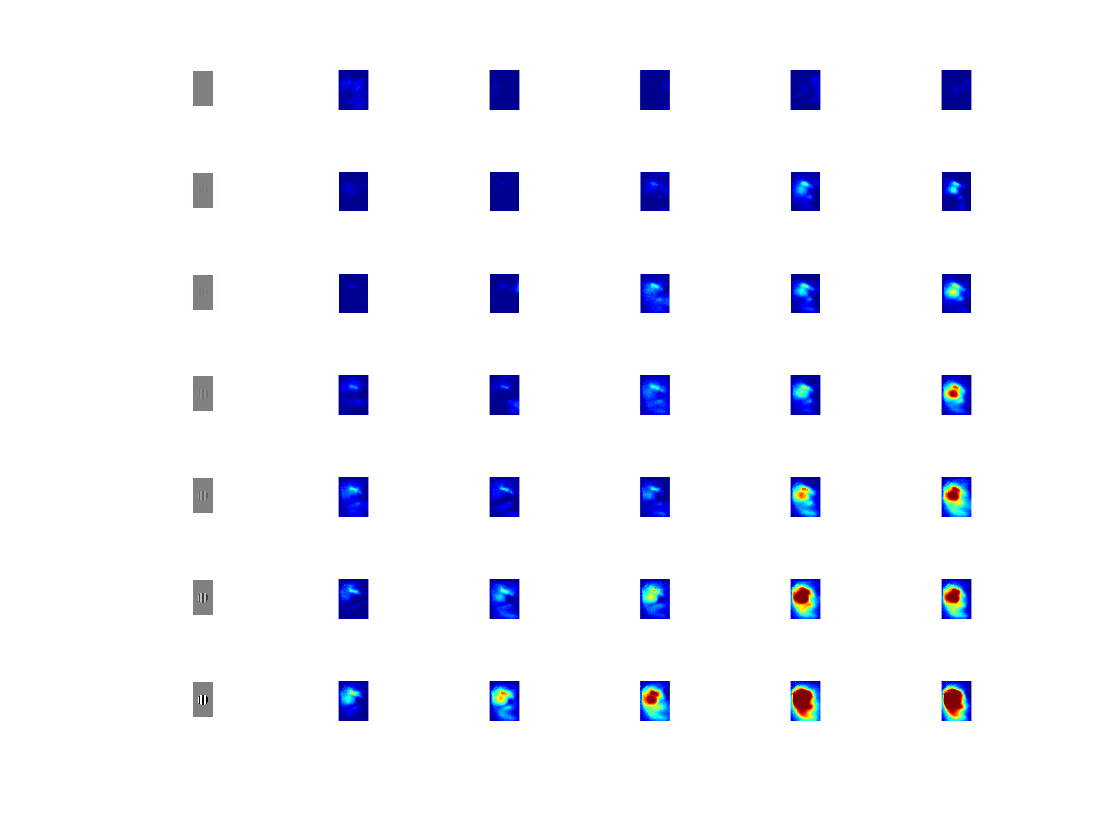


fntSize = 10;
fntName = 'SansSerif';
fontMult = 1.5;

set(gca, 'FontSize', fntSize, 'FontName', fntName)

% Give common xlabel & ylabel
han=axes(fig,'visible','off'); 
han.XLabel.Visible='on';
han.YLabel.Visible='on';
ylabel(han,'contrast');
xlabel(han,'duration');

% ylabel('contrast (%)', 'FontSize', fntSize*fontMult, 'FontName', fntName)
% yt = [0 0.03 0.0625 0.125 0.25 0.5 1];
% ytl = arrayfun(@num2str, yt, 'UniformOutput', 0);
% set(gca,'YTick',yt)
% set(gca,'YTickLabel',ytl)


%xlabel('duration (sec)', 'FontSize', fntSize*fontMult, 'FontName', fntName)
%xt = [0:400:xMax];
%xt = [0:5:ceil(length(meanPupVal_normalized_allTrial_allSess{1,n})*frameRate)];
%xtl = arrayfun(@num2str, xt, 'UniformOutput', 0);
%set(gca,'xtick',xt); 
%set(gca,'xticklabel',xtl);
